# Define Space in which the wave will propagate

clear;
clc;

c = 1500                           % The speed of sound in water

c = 1500

f = 40000;                         % Frequency of Sound Wave
lamda = f/c;                       % Wavelength
w = 2*pi*f;                        % The temporal Frequency
k = 2*pi/lamda;                    % The Wave Number/ Wave Vector
A = 2;                             % The amplitude of the sources- (All sources will propagate the same Amplitude)
phase1 = pi;                       % The initial phase of source 2
phase2 = 0;                        % The initial phase of source 1
x = -0.8:0.02:0.8;                % x Range of distance travelled into the liquid
y = -0.4:0.001:0.4;                % y Range of distance travelled into the liquid
z = 0:0.008:0.5;                   % z Range of distance travelled into the liquid


% Create a Grid of x,y,z values to use in Calculation of values in the 3-D
% Space
[X, Y, Z] = ndgrid(x, y, z);
X = X(:); Y = Y(:); Z = Z(:); % Make column vectors
length(X)

ans = 4087503

% This set of vectors represent the x,y,z coordinates of the Utrasound
% Sources
SrcePositions = [-0.05,0,0;0.05,0,0];  % Two Sources on the x axis, 0.1m away from each other

% Define the Delay /Phase for each source, Each value in the array
% Corresponds to the source in the Source Positions array
delay = [0 0.2786];


# The Sinusoid Sound waves

pressureValue= [];                % An array representing the pressure values
intensity = [];                   % An array representing the intensity of the sound wave
for i = 1:length(X)
    TotalSIP=0;
    for SrceVal = 1
        pressure = 0;
        dist = transdis(X(i), Y(i), Z(i), SrcePositions(SrceVal,:));           % Distance from trasducer the Source
        pressure = (1/dist)*A*cos(k*dist-w*(SrceVal-delay(SrceVal)));          % Pressure calculated due to source @ SrceVal
        TotalSIP = TotalSIP + pressure;                                        % Sum up the Pressure values to represent the Superpositon of the Waves
    end
    pressureValue(i) = abs(TotalSIP);
    intensity(i) = (TotalSIP^2)/(2*1.2754*c);
end

pressureValue = pressureValue(:);
intensity = intensity(:);

% BEAM
beam = [];
xb = [];
yb = [];
zb = [];

for i = 1:length(pressureValue)
    if (pressureValue(i)>15)
        beam = [beam; pressureValue(i)];
        xb= [xb; X(i)];
        yb= [yb; Y(i)];
        zb= [zb; Z(i)];
    end
end



# Plot the Waves

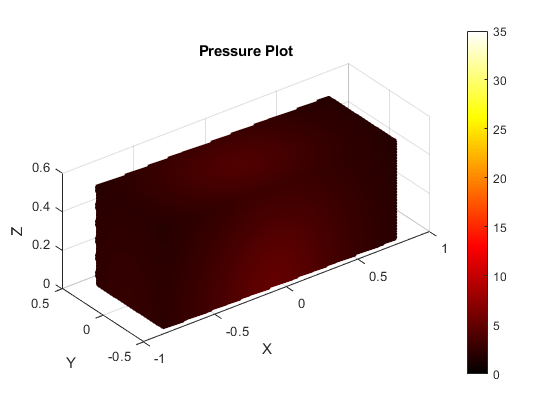

% Pressure
figure
scatter3(X,Y,Z,30,pressureValue,'filled')     
colormap hot
colorbar;
caxis([0 35])
pbaspect([2.7 1 1])
title('Pressure Plot');
xlabel('X'); ylabel('Y'); zlabel('Z')
hold on

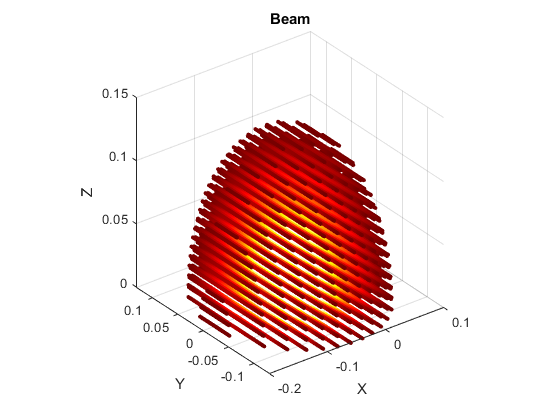

% Scatter3(0, 0, 0.03,100, 'r', 'filled') 


% Pressure Beam
figure
scatter3(xb,yb,zb,10,beam, 'filled')       
colormap hot
pbaspect([1 1 1])
caxis([10 40])
title('Beam');
xlabel('X'); ylabel('Y'); zlabel('Z') 


% figure
% plot(X,pressureValue)
% colormap autumn


# Calculate the distance from the source to the point of measurement

function d = transdis(x, y, z, t)
    d = sum(([x y z]-t).^2).^0.5;
end